clear
simTimEnd=10;
samplingTime=0.01;
Ac=[0,2;-0.8,2];
Ad=(eye(2)+Ac*samplingTime);
Bc=eye(2);
Bd=samplingTime*Bc;


% Generating intial condition:
%In general, you can generate N
%random numbers in the interval (a,b) 
% with the formula r = a + (b-a).*rand(N,1).
a=-2;
b=2;

x(1,1)=a+(b-a)*rand();
x(2,1)=a+(b-a)*rand();

%Generating/Simulation some data to work with:

index=2; %Index to save some numbers 

for i=0:samplingTime:simTimEnd
    %Determing input
    u(:,index-1)=[sin(2*i);sin(i)];

    x(:,index)=Ad*x(:,index-1)+samplingTime*[0;-10*x(1,index-1)^2*x(2,index-1)]+Bd*u(:,index-1);    
    index=index+1; 
end
%Collecting x and u into one matrix
xAll=x

xAll =     1.2589    1.2914    1.3193    1.3432    1.3635    1.3806    1.3950    1.4070    1.4172    1.4258    1.4331    1.4394    1.4449    1.4497    1.4541    1.4581    1.4619    1.4655    1.4690    1.4724    1.4759    1.4794    1.4829    1.4866    1.4903    1.4942    1.4982    1.5024    1.5067    1.5111    1.5158    1.5205    1.5255    1.5306    1.5359    1.5413    1.5469    1.5526    1.5585    1.5646    1.5708    1.5772    1.5837    1.5903    1.5971    1.6041    1.6112    1.6184    1.6257    1.6332
    1.6232    1.3883    1.1743    0.9831    0.8149    0.6692    0.5445    0.4389    0.3502    0.2763    0.2152    0.1648    0.1235    0.0899    0.0625    0.0403    0.0223    0.0079   -0.0037   -0.0129   -0.0203   -0.0261   -0.0306   -0.0342   -0.0369   -0.0390   -0.0406   -0.0417   -0.0425   -0.0430   -0.0432   -0.0433   -0.0433   -0.0431   -0.0429   -0.0426   -0.0422   -0.0418   -0.0414   -0.0409   -0.0404   -0.0399   -0.0394   -0.0389   -0.0384   -0.0379   -0.0374   -0.0369   -0.0364  

uAll=u

uAll =          0    0.0200    0.0400    0.0600    0.0799    0.0998    0.1197    0.1395    0.1593    0.1790    0.1987    0.2182    0.2377    0.2571    0.2764    0.2955    0.3146    0.3335    0.3523    0.3709    0.3894    0.4078    0.4259    0.4439    0.4618    0.4794    0.4969    0.5141    0.5312    0.5480    0.5646    0.5810    0.5972    0.6131    0.6288    0.6442    0.6594    0.6743    0.6889    0.7033    0.7174    0.7311    0.7446    0.7578    0.7707    0.7833    0.7956    0.8076    0.8192    0.8305
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0699    0.0799    0.0899    0.0998    0.1098    0.1197    0.1296    0.1395    0.1494    0.1593    0.1692    0.1790    0.1889    0.1987    0.2085    0.2182    0.2280    0.2377    0.2474    0.2571    0.2667    0.2764    0.2860    0.2955    0.3051    0.3146    0.3240    0.3335    0.3429    0.3523    0.3616    0.3709    0.3802    0.3894    0.3986    0.4078    0.4169    0.4259    0.4350    0.4439    0.4529    0.4618  

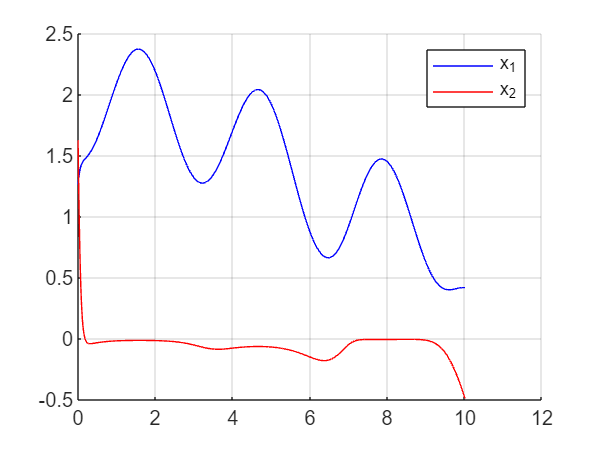

%Plotting the generated data:
time=0:samplingTime:simTimEnd+samplingTime; 
clf
hold on 
plot(time,x(1,:),'blue')
plot(time,x(2,:),'red')
hold off 
grid
legend('x_1','x_2')

%Making the Hankel matrix, which will be based on 5050 points, and a delay
%of 50  (therefore from 1 to 5000 or from 50 to 5049!:

n=size(xAll,1);

d=50;
m=500; 
index=1;

for i=0:d
    H(index:index+n-1,:)=xAll(:,d-i+1:m-i);
    index=index+n;
end

%Takning the SVD of the Hankel matirx 
[U,S,V]=svd(H);


%Making the short version of the matrixs, based on trails 


    R=7; 
    Vr=V(:,1:R);
    Sr=S(1:R,1:R);
    Ur=U(:,1:R);

    cond(Sr)

ans = 2.7757e+03

   
    %Making the concurrent and predict V based on the small V
    VrCon=Vr(1:end-1,:);
    VrPred=Vr(2:end,:);
    %Making transformation such that it is possible to transfer the matrix
    %to the V subspace
    Pup=(Ur*Sr);

    Pdown=pinv(Ur*Sr);

    %Making the Hankel matrix for the input series used for the
    %Measurement time series made eariliere. 
    index=1;

    d=50;
    m=m-1; 
    index=1;

    for i=0:d
        Hu(index:index+n-1,:)=uAll(:,d-i+1:m-i);
        index=index+n;
    end


    %Transforming the input series into the V space. 
    u=Pdown*Hu;
    
    %Making the G matrix
    G=[transpose(VrCon);u];

    
%Approximation the koopman operation A and B: 
temp=transpose(VrPred)*pinv(G);

%Splitting A and B up: 

A=temp(:,1:R); 
B=temp(:,R+1:end);
    

   
    




    %The times series of measurement and input
    % which is project to V, needs to have the same amout
    %of rows as H, as a delay of 50 was used and 2 states and 2 inputs
    % is present which
    %corresponds to 100 rows, therefore 99 present and the current sample
    %is used. The "model" was train on data from 0 to 549, therefore the 
    % time series starts at 451 to 550 and builds up to 1000

    %To only pickout the predited output instead of the entire sequences
    ny=2;
    Cc=[1, zeros(1,ny*(d+1)-1);0,1,zeros(1,ny*(d+1)-2)];

%Making one step prediction with input
for i=1:500
    %Taking out the 100 samples
      clear Hr;
    index=1;
    for j=d+i:-1:i
        Hr(index:index+n-1,:)=xAll(:,500-d+j);
        index=index+n;
    end

    clear Hru 
     index=1;
    for j=d+i:-1:i
        Hru(index:index+n-1,:)=uAll(:,500-d+j);
        index=index+n;
    end



    %Projecting to the V subspace: 
    Vk=Pdown*Hr; %Is v^T
    %Projecting inputs to V subspace:
    uk=Pdown*Hru;

    %Making prediction:
    PredictionV=A*Vk+B*uk;  %Prediction of V^T


    %Transforming the prediction back to the state space representation
    PreditionX=Pup*PredictionV; %PredictionV is already transpose and therefore no transpose here! 

    %Only takning out the newest/predict value of x, and forgetting the
    %rest of the time series ;D 
    PredictionXsave(:,i)=Cc*PreditionX; 
    %PredictionXsave(:,i)=transpose(PreditionX(end,:));
end 



%Making plots of the estimation and the true simulated values for one step
%esitmation

time2=0:samplingTime:simTimEnd/2-51*samplingTime;
clf
hold on 
plot(xAll(1,500:1000-1),'blue')
plot(PredictionXsave(1,:),'red')
hold off 
grid
legend('x_1 true','x_1 estimated one step',"x_1 est one step, no input",'location','best')

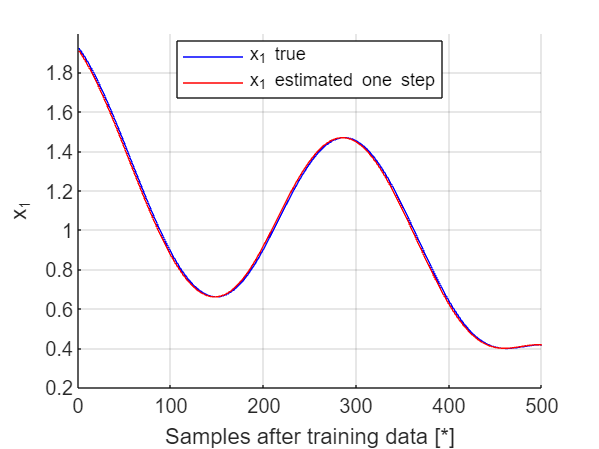

xlabel("Samples after training data [*]")
ylabel('x_1')

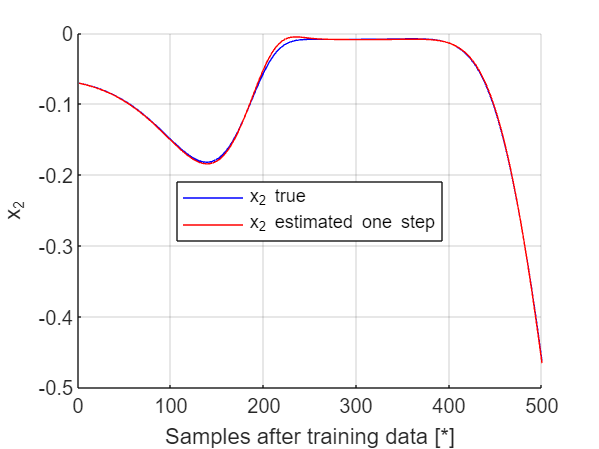

ax=gca;
%exportgraphics(ax,"x1_HAVOK_with_input.pdf")


clf
hold on 
plot(xAll(2,500:1000-1),'blue')
plot(PredictionXsave(2,:),'red')

hold off 
grid
legend('x_2 true','x_2 estimated one step','location','best')
xlabel("Samples after training data [*]")
ylabel('x_2')


ax=gca;
%exportgraphics(ax,"x2_HAVOK_with_input.pdf")

%Making multiple step prediction with input 

%Taking out the 100 samples
    i=1;
    clear Hr;
    index=1;
    for j=d+i:-1:i
        Hr(index:index+n-1,:)=xAll(:,500-d+j);
        index=index+n;
    end
for i=1:500
    %Taking out the 100 data inputs: 
    clear Hru 
     index=1;
    for j=d+i:-1:i
        Hru(index:index+n-1,:)=uAll(:,500-d+j);
        index=index+n;
    end

    %Projecting to the V subspace: 
    Vk=Pdown*Hr; %Is v^T
    %Projecting inputs to V subspace:
    uk=Pdown*Hru;

    %Making prediction:
    PredictionV=A*Vk+B*uk;  %Prediction of V^T


    %Transforming the prediction back to the state space representation
    PreditionX=Pup*PredictionV; %PredictionV is already transpose and therefore no transpose here! 

    %Only takning out the newest/predict value of x, and forgetting the
    %rest of the time series ;D 
    PredictionXsaveMulti(:,i)=Cc*PreditionX; 
    %PredictionXsave(:,i)=transpose(PreditionX(end,:));
    Hr=[ Cc*PreditionX; Hr(1:end-n,:)];
end 


%Plotting the graphs

time2=0:samplingTime:simTimEnd/2-51*samplingTime;
clf
hold on 
plot(xAll(1,500:1000-1),'blue')
plot(PredictionXsaveMulti(1,:),'red')
hold off 
grid
legend('x_1 true','x_1 estimated multi step',"x_1 est multi step, no input",'location','best')

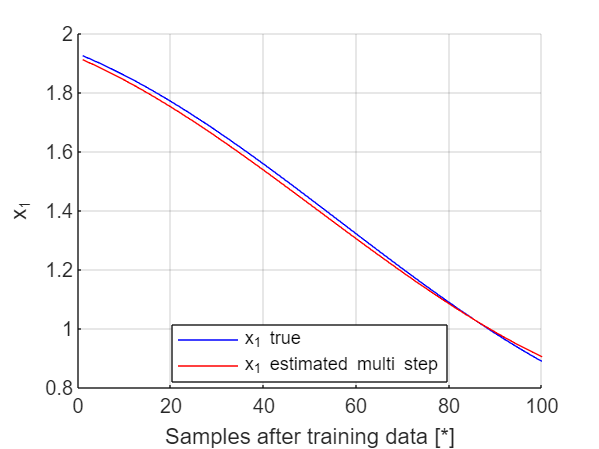

xlabel("Samples after training data [*]")
ylabel('x_1')
xlim([0 100])

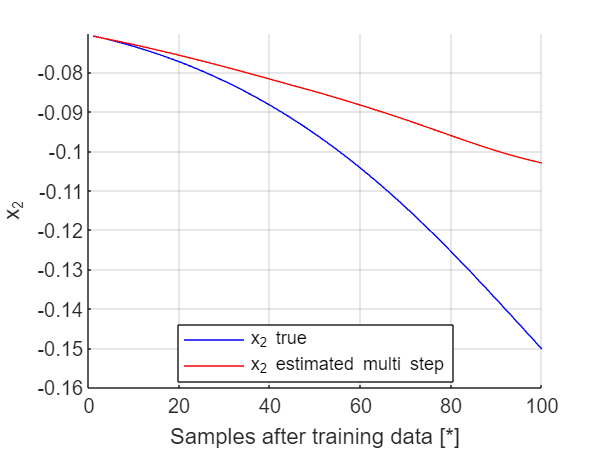


ax=gca;
%exportgraphics(ax,"x1_HAVOK_with_input_multi.pdf")

clf
hold on 
plot(xAll(2,500:1000-1),'blue')
plot(PredictionXsaveMulti(2,:),'red')

hold off 
xlim([0 100])
grid
legend('x_2 true','x_2 estimated multi step','location','best')
xlabel("Samples after training data [*]")
ylabel('x_2')


ax=gca;
%exportgraphics(ax,"x2_HAVOK_with_input_multi.pdf")

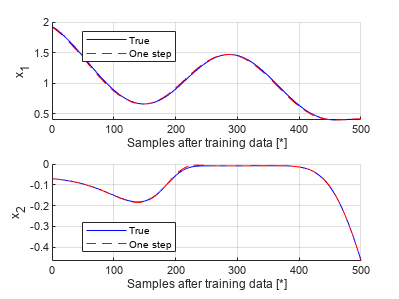

%Plotting one step prediction for x1 and x2 
clf
%Plotting x1
subplot(2,1,1) 
 hold on 
plot(xAll(1,500:1000-1),'blue')
plot(PredictionXsave(1,:),'--red')
hold off 
grid on
legend('True','One step','location','best')
xlabel("Samples after training data [*]")
ylabel('x_1')
%title('One step prediction')

%Plotting x2 
subplot(2,1,2)

hold on 
plot(xAll(2,500:1000-1),'blue')
plot(PredictionXsave(2,:),'--red')

hold off 
grid
legend('True','One step','location','best')
xlabel("Samples after training data [*]")
ylabel('x_2')

exportgraphics(gcf,"Test_HAVOKc_one_step_prediction.pdf",'ContentType','vector')

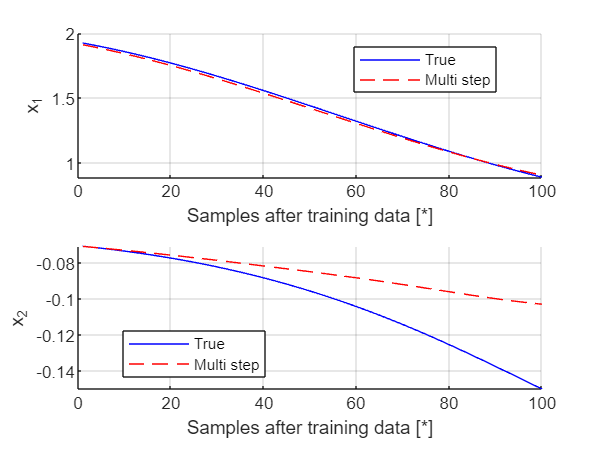

%Plotting multi step prediction 
clf 
%Plotting x1 
subplot(2,1,1)
hold on 
plot(xAll(1,500:1000-1),'blue')
plot(PredictionXsaveMulti(1,:),'--red')
hold off 
grid
legend('True','Multi step','location','best')
xlabel("Samples after training data [*]")
ylabel('x_1')
xlim([0 100])

%Plotting x2 
subplot(2,1,2)
hold on 
plot(xAll(2,500:1000-1),'blue')
plot(PredictionXsaveMulti(2,:),'--red')

hold off 
xlim([0 100])
grid
legend('True','Multi step','location','best')
xlabel("Samples after training data [*]")
ylabel('x_2')


%exportgraphics(gcf,"Test_HAVOKc_multi_step_prediction_2.pdf",'ContentType','vector')

